# Example: Enzymatic Catalysis

**Main file of the enzymatic catalysis example, demonstrates the use of:**

- getMultiStarts()

- getParameterProfiles()

- integrateParamterProfiles()

 This example provides a model for the reaction of a species $X_1$ to a species $X_4$ which is catalyzed by an enzyme $X_2$.

-  
$$X_1 + X_2 \longrightarrow X_3\, , \qquad \text{rate} = \theta_1 \cdot [X_1] \cdot [X_2]$$


-  
$$X_3 \longrightarrow X_1 + X_2\, , \qquad\text{rate} = \theta_2 \cdot [X_3]$$


-  
$$X_3 \longrightarrow X_2 + X_4\, , \qquad \text{rate} = \theta_3 \cdot [X_3]$$


-  
$$X_2 + X_4 \longrightarrow X_3\, , \qquad \text{rate} = \theta_4 \cdot [X_2] \cdot [X_4]$$


Measurements of $[X_1]$ and $[X_4]$ are provided as: $Y = \big( \, [X_1], [X_4] \, \big)^T$

This file fixes a parameter vector, creates and saves artificial measurement data as a time series and performs a multi-start local optimization based on these measurements, demonstrating the use of getMultiStarts().

The Profile likelihoods are calculated in two different ways: First, the calculation is done by repeated reoptimization using getParameterProfiles(), then it is done by integrating the an ODE along the profile path using integrateParameterProfiles().

## Preliminary

clear all;
close all;
clc;

TextSizes.DefaultAxesFontSize = 10;
TextSizes.DefaultTextFontSize = 14;
set(0,TextSizes);

## Model Definition

See logLikelihood.m for a detailed description

## Create Artificial Data for Parameter Estimation

The necessery variables are set (Parameter bounds, variance, ...)

nTimepoints = 100;      % Time points of Measurement
nMeasure    = 5;        % Number of experiments
sigma2      = 0.05^2;   % Variance of Measurement noise
lowerBound  = -10;      % Lower bound for parameters
upperBound  = 5;        % Upper bound for parameters
theta       = [1.1770; -2.3714; -0.4827; -5.5387]; % True parameter values

**Creation and writing of data to files**

Once the two files getMeasuredData.m and getInitialConcentrations.m are written, the following line can be commented

performNewMeasurement(theta, nMeasure, nTimepoints, sigma2);


The measurement data is read out from the files where it is saved

yMeasured = getMeasuredData();
con0 = getInitialConcentrations();

## Generation of the structs and options for PESTO

The structs and the PestoOptions object, which are necessary for the PESTO routines to work are created and set to convenient values

**Parameters**

parameters.name = {'log(theta_1)', 'log(theta_2)', 'log(theta_3)', 'log(theta_4)'};
parameters.min = lowerBound * ones(1, 4);
parameters.max = upperBound * ones(1, 4);
parameters.number = length(parameters.name);


**Objective function**

objectiveFunction = @(theta) logLikelihoodEC(theta, yMeasured, sigma2, con0, nTimepoints, nMeasure);


**Pesto Options**

optionsMultistart           = PestoOptions();
optionsMultistart.n_starts  = 15;
optionsMultistart.obj_type  = 'log-posterior';
optionsMultistart.comp_type = 'sequential'; 
optionsMultistart.mode      = 'visual';
optionsMultistart.plot_options.add_points.par = theta;
optionsMultistart.plot_options.add_points.logPost = objectiveFunction(theta);

## Perform Multistart Optimization

A multi-start local optimization is performed within the bound defined in parameters.min and .max in order to infer the unknown parameters from measurement data.

**getMultiStarts()**

-> Multi-start optimization FINISHED.


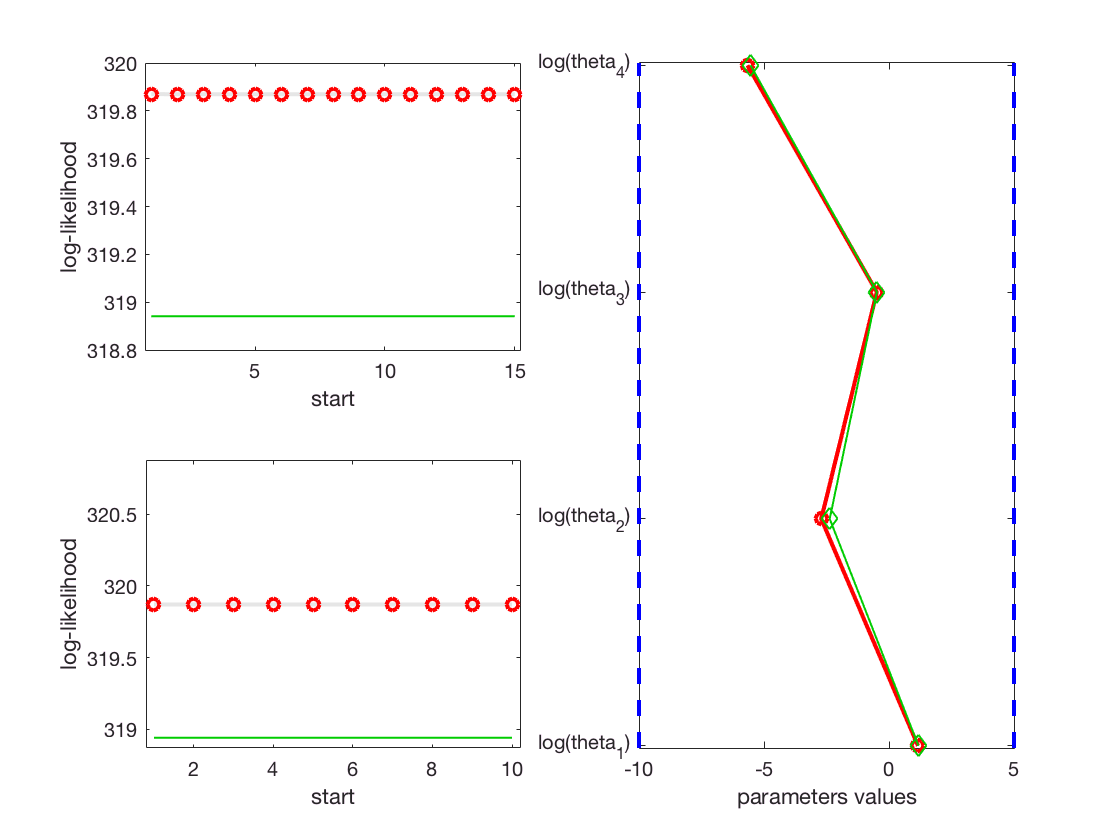

parameters = getMultiStarts(parameters, objectiveFunction, optionsMultistart);

## Calculate profile likelihoods I

The uncertainty of the estimated parameters is visualized by computing and plotting profile likelihoods. In getParameterProfiles, this is done by using repeated reoptimization

**getParameterProfiles()**

1st P: point 0, R = 9.704e-01 (optimized) / 9.073e-01 (predicted)
1st P: point 1, R = 8.809e-01 (optimized) / 8.807e-01 (predicted)
1st P: point 2, R = 7.492e-01 (optimized) / 7.490e-01 (predicted)
1st P: point 3, R = 5.948e-01 (optimized) / 5.946e-01 (predicted)
1st P: point 4, R = 4.392e-01 (optimized) / 4.390e-01 (predicted)
1st P: point 5, R = 2.724e-01 (optimized) / 2.723e-01 (predicted)
1st P: point 6, R = 1.507e-01 (optimized) / 1.503e-01 (predicted)
1st P: point 7, R = 6.090e-02 (optimized) / 6.075e-02 (predicted)
1st P: point 8, R = 1.502e-02 (optimized) / 1.491e-02 (predicted)
1st P: point 9, R = 9.659e-01 (optimized) / 9.075e-01 (predicted)
1st P: point 10, R = 8.759e-01 (optimized) / 8.755e-01 (predicted)
1st P: point 11, R = 7.462e-01 (optimized) / 7.461e-01 (predicted)
1st P: point 12, R = 5.980e-01 (optimized) / 5.979e-01 (predicted)
1st P: point 13, R = 4.178e-01 (optimized) / 4.176e-01 (predicted)
1st P: point 14, R = 2.665e-01 (optimized) / 2.664e-01 (predicted)
1st P

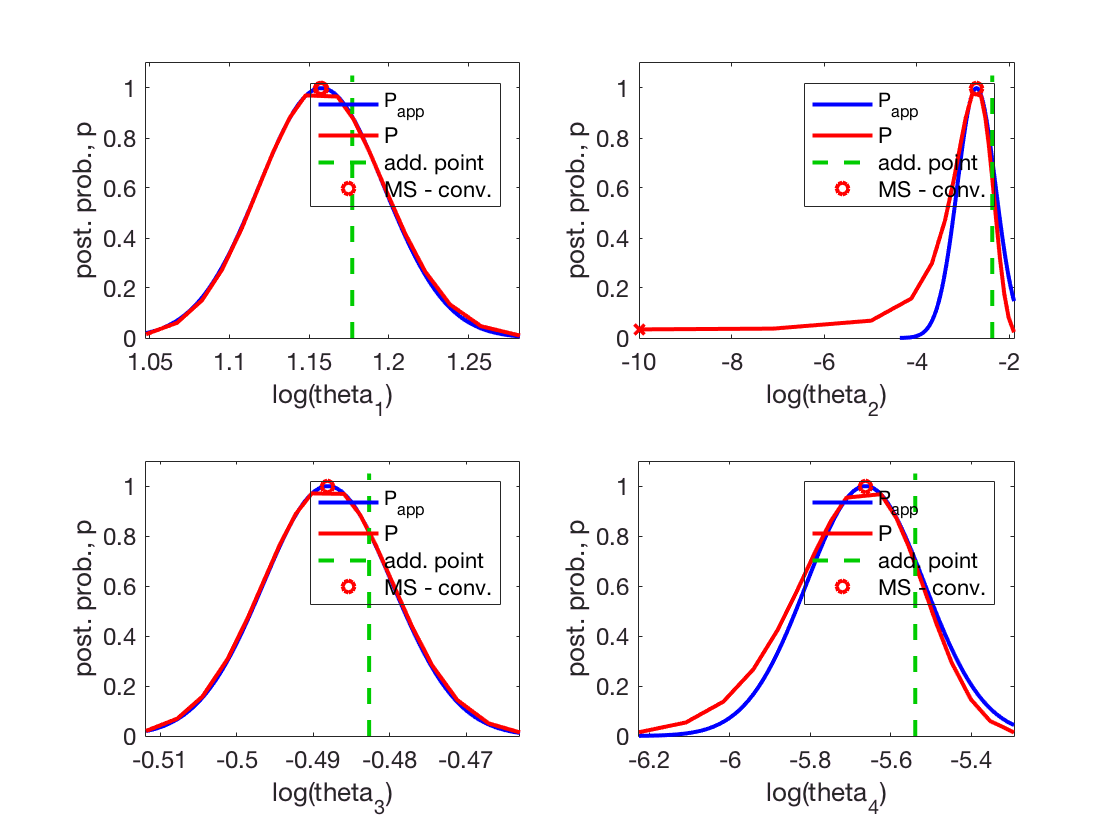

% parameters = getParameterProfiles(parameters, objectiveFunction, optionsMultistart);